# Time Analysis Program

Author: M. Noyce 

Description: Simple Program to extract the time series data

## Import Raw Data

%Specify directory of text file data 
projectdir = "C:\Users\uctsh\Documents\MATLAB\SHARC_BUOY_06_RAW_DATA\WD"; 
outdir = "C:\Users\uctsh\Documents\MATLAB\waveOutput";
outdir_2 = "C:\Users\uctsh\Documents\MATLAB";

%List wave data folders
folders = dir(projectdir);

%Sort List of folders 
folders = natsortfiles(folders);

%concatenate text files into one file for each folder 
%Each file has 6x5 minute time series in seperate text files

%Loop over every folder 
for folderCount = 1 : numel(folders)
    

    concatFile = sprintf("WS%d.txt", folderCount);
    subfolder = sprintf("WS%d", folderCount);
    outFileName = fullfile(outdir, concatFile); 
    outFile = fopen(outFileName, "w");
    
    subfoldername = fullfile(projectdir, subfolder);
    files = dir(subfoldername);
    files = natsortfiles(files);

    %concatenate files in subfolder
    for fileCount = 1 : length(files)
        
        filename = fullfile(subfoldername, files(fileCount).name);
        
        if isfile(filename)    
            tempfile = fopen(filename, 'r');
            tempData = fread(tempfile, 'uint8');
            fwrite(outFile, tempData, 'uint8');
            fclose(tempfile); 
        else 
            fprintf('File does not exist.\n'); 
        end
    
    end
    
    fclose("all");

end

File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not

## Create Text file with full dataset


outFileName = fullfile(outdir_2, "WS_All.txt"); 
outFile = fopen(outFileName, "w"); 

files = dir(outdir);
files = natsortfiles(files);

%Create concatenated text file with all data
for fileCount = 1 : length(files) 
        
        filename = fullfile(outdir, files(fileCount).name);
        
        if isfile(filename)    
            tempfile = fopen(filename, 'r');
            tempData = fread(tempfile, 'uint8');
            fwrite(outFile, tempData, 'uint8');
            fclose(tempfile); 
        else 
            fprintf('File does not exist.\n'); 
        end
    
end

File does not exist.
File does not exist.


    
fclose("all");
   

## Read Data into Table 

%Specify variables
opts = delimitedTextImportOptions("NumVariables", 7);
opts.VariableNames = ["TimeUTC","Surge", "Sway", "Heave", "Roll", "Pitch", "Yaw"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double"];

%Read in table
wavefile = fullfile(outdir_2, "WS_All.txt");
WaveTable = readtable(wavefile, opts);


## Add dates to Table 

%Data has time but not date values, this code segment adds date values

%Covert Time values in table to datetime format 
WaveTable.TimeUTC = datetime(WaveTable.TimeUTC, 'Format','yyyy-MM-dd HH:mm:ss.SSS');

%calculate new day increment
newday = [true; diff(WaveTable.TimeUTC)<0];
daynum = cumsum(newday);

%Create array of days
date = datetime(2022, 07, 20) + caldays(daynum - 1); 
DateTimeUTC = date + timeofday(WaveTable.TimeUTC); 

%Add datetime 
WaveTable = addvars(WaveTable, DateTimeUTC, 'before', "TimeUTC"); 
WaveTable.TimeUTC = [];

%Specify Times after deployment 
WaveTable = WaveTable(WaveTable.DateTimeUTC > datetime(2022, 07, 20, 19, 10, 00), :);

## Differentiate Time Series on Table

%Add Count Label to differentiate between time series
newTimeSeries= [true; diff(WaveTable.DateTimeUTC)> minutes(5)];
timeSeriesCount = cumsum(newTimeSeries);
TimeSeriesNo = max(timeSeriesCount); 
WaveTable = addvars(WaveTable, timeSeriesCount, 'After', 'DateTimeUTC');

## Convert individual wave series sample to timetable 

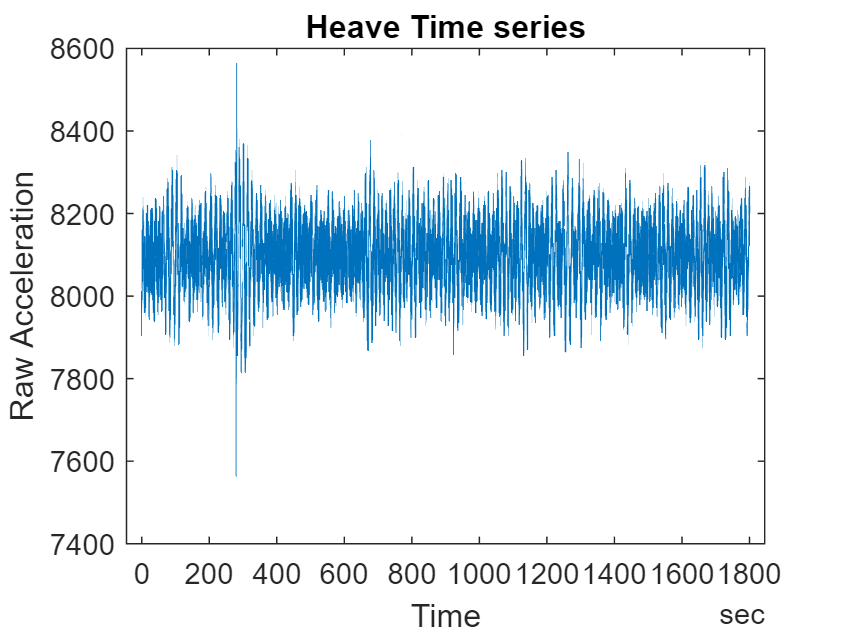

%Create 30 minute time vector with ms resolution 
Fs = 100;
Ts = 1/Fs;

%Sample of Interest
WaveSample = 50;

%Convert Wave Sample of Interest to TimeTable
WaveSampleTable = WaveTable(WaveTable.timeSeriesCount == WaveSample, :); 
WaveTimeTable = table2timetable(WaveSampleTable, 'SampleRate', Fs);

%%TODO
%%Fix the time issue (~15 second offset by using retime)
%WaveTimeTable = retime(WaveTimeTable, 'regular', 'linear', 'SampleRate', Fs); 

%Plot raw signal 
plot(WaveTimeTable.Time, WaveTimeTable.Heave);
title("Heave Time series");
xlabel("Time");
ylabel("Raw Acceleration"); 

## Create Cell Array of TimeTables


for i = 1 : TimeSeriesNo

    WaveSampleTable = WaveTable(WaveTable.timeSeriesCount == TimeSeriesNo, :); 
    WaveTimeTable = table2timetable(WaveSampleTable, 'SampleRate', Fs);

end

## Preprocess Acceleration Signal

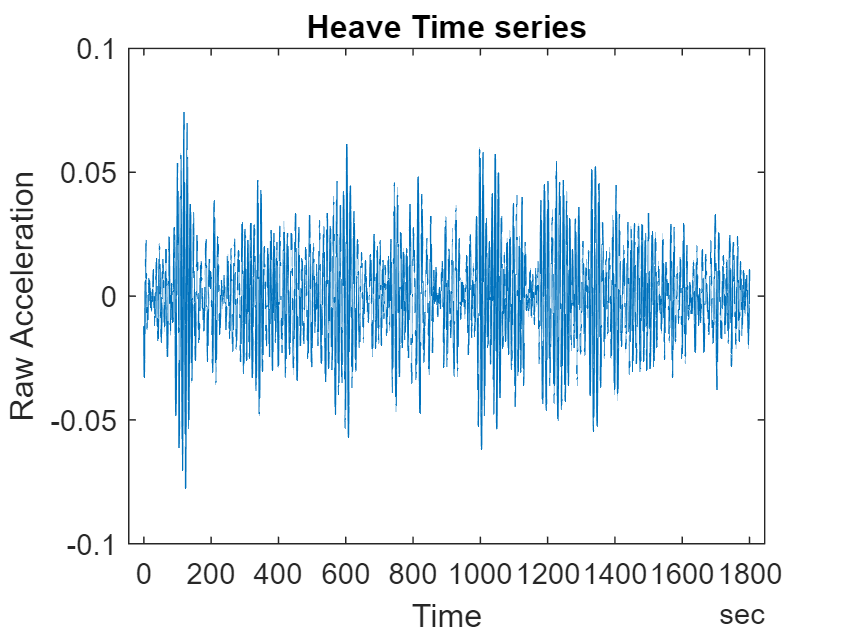

% Scale 
Heave = WaveTimeTable.Heave / 8192 - ( 9.81 * 8192 ); 
%Detrend 
Heave = detrend(Heave);
%Lowpass filter 
Heave = lowpass(Heave, 2, 100);

%Plot Pre-processed signal 
plot(WaveTimeTable.Time, Heave);
title("Heave Time series");
xlabel("Time");
ylabel("Raw Acceleration"); 

## Spectral Analysis of single raw time series (acceleration) 

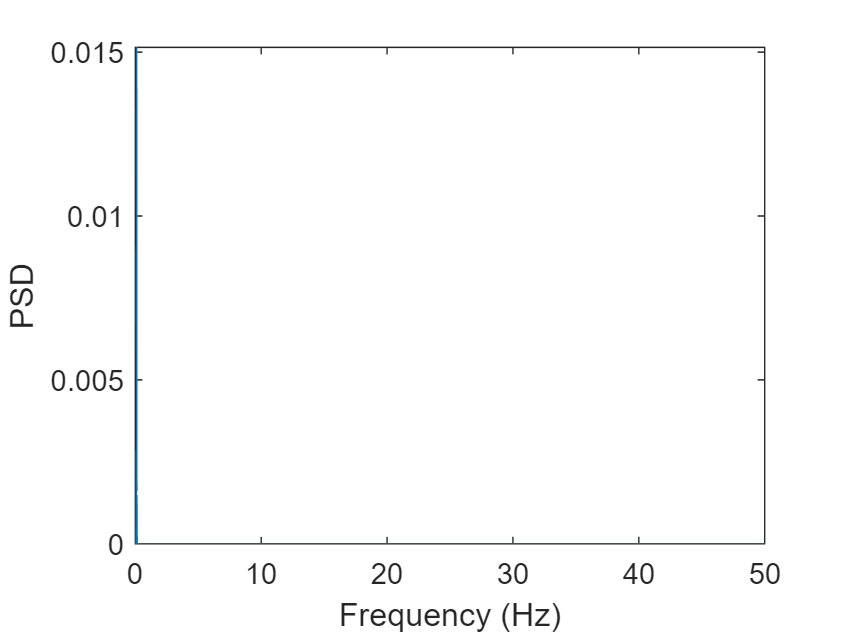

%Welch Method
Window = 5 * 60 * 100; 
segmentLength = 60*5*100;
nooverlap = segmentLength/2; 

[pxx, f] = pwelch(Heave, segmentLength, [], segmentLength, 100, "onesided"); 

%Plot Acceleration PSD 
plot(f, pxx);
xlabel('Frequency (Hz)')
ylabel('PSD')

## Integration to Displacement

%Tranform to the frequency domain 
y = fft(Heave);
y = fftshift(y);

%Double integration in the frequency domain

f1 = 0.02; %Lower corner frequency for half cosine taper
f2 = 0.03; %Upper frequency for half cosine taper
fc = 1; 

Nfft = length(y);

%frequency array 
f = Fs*(-Nfft/2:1:Nfft/2-1)'./Nfft

f =   -50.0000
  -49.9994
  -49.9989
  -49.9983
  -49.9978
  -49.9972
  -49.9967
  -49.9961
  -49.9956
  -49.9950


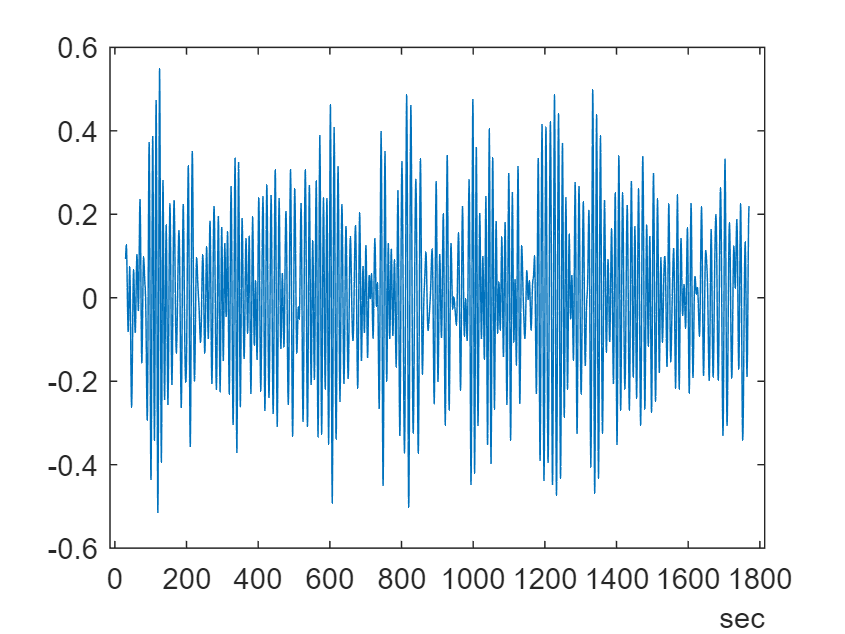

N = size(f, 1); 

%Fourier filter 
% Rf = response frequency weights
Rf = zeros(N, 1);

for i = 1:length(f)
    if f(i) < f1 
       Rf(i, 1) = 0;
    end
        if f(i) > f1 & f(i) < f2
            Rf(i, 1) = (1/2)*(1-cos(pi*(f(i)-f1)/(f2-f1))*(-1/(2*pi*f(i)^2)));
        end
            if f(i) > f2 & f(i) < fc
                Rf(i, 1) = -1/(2*pi*f(i)^2); 
            end
end

%Acceleration .* Rf
elevFFT = y.*Rf; 

%Elevation 
elev = ifft(fftshift(elevFFT)); 

%Remove 30s from each side 
sec_30 = Fs*30; 
elev = real(elev);
elev = elev(sec_30:(end-sec_30));

%Plot elevation output 
timeSeries = WaveTimeTable.Time(sec_30:(end-sec_30));
plot(timeSeries, elev);

## PSD Estimate (Welch's Method)

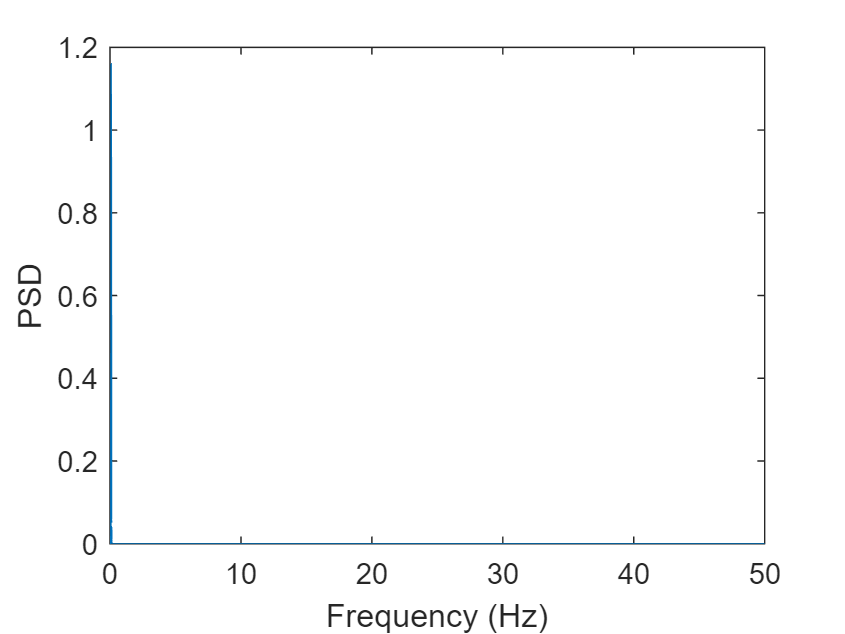

%Welch Method
Window = 5 * 60 * 100; 
segmentLength = 60*5*100;
nooverlap = segmentLength/2; 

[pxx, f] = pwelch(elev, segmentLength, [], segmentLength, 100, "onesided"); 

%Plot Acceleration PSD 
plot(f, pxx);
xlabel('Frequency (Hz)')
ylabel('PSD')

## Extraction of wave parameters 

Credit: SWASH Model 

m=length(pxx);
%number of subintervals
m=m-1;
%length of the subinterval
Ax=(f(m+1)-f(1))/m;
%Integral I1 m0=int{E(f)df} I1
s=0;
for i=2:m
 s=s+pxx(i); %sum(2,m) f(xi)
end

m0=0.5*Ax*(pxx(1)+2*s +pxx(m+1));

%Integral I2 m1=int{f*E(f)df} I2
s=0;
%f=f*E(f)=f*mW
for i=2:m
 s=s+f(i)*pxx(i);
end

m1=0.5*Ax*(f(1)*pxx(1)+2*s+f(m+1)*pxx(m+1));


Hm0 = 4*sqrt(m0);
Tm01 = m0/m1; 